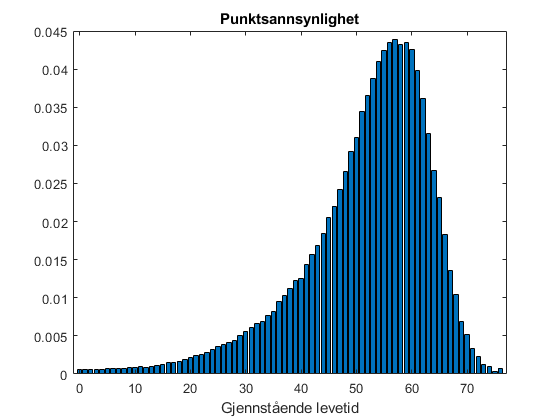

% for aa plotte punktsannsynligheten trengs, den kumulative fordelingen:

    % for å regne ut den kumulative fordelingen trengs, den ettaarlige doedssannsynlighetene:
    
        %finner den ettaarlige doedssannsynlighetene
qk = dod/1000;

    %finner saa den kumulative fordelingen
Fx = 1-cumprod(1-qk(31:107));

% Beregner punktsannsynlighetne
px = Fx -[0;Fx(1:76)];

%plotter punktsannsynlighetene
bar(0:76,px)
xlabel("Gjennstående levetid")
title("Punktsannsynlighet")